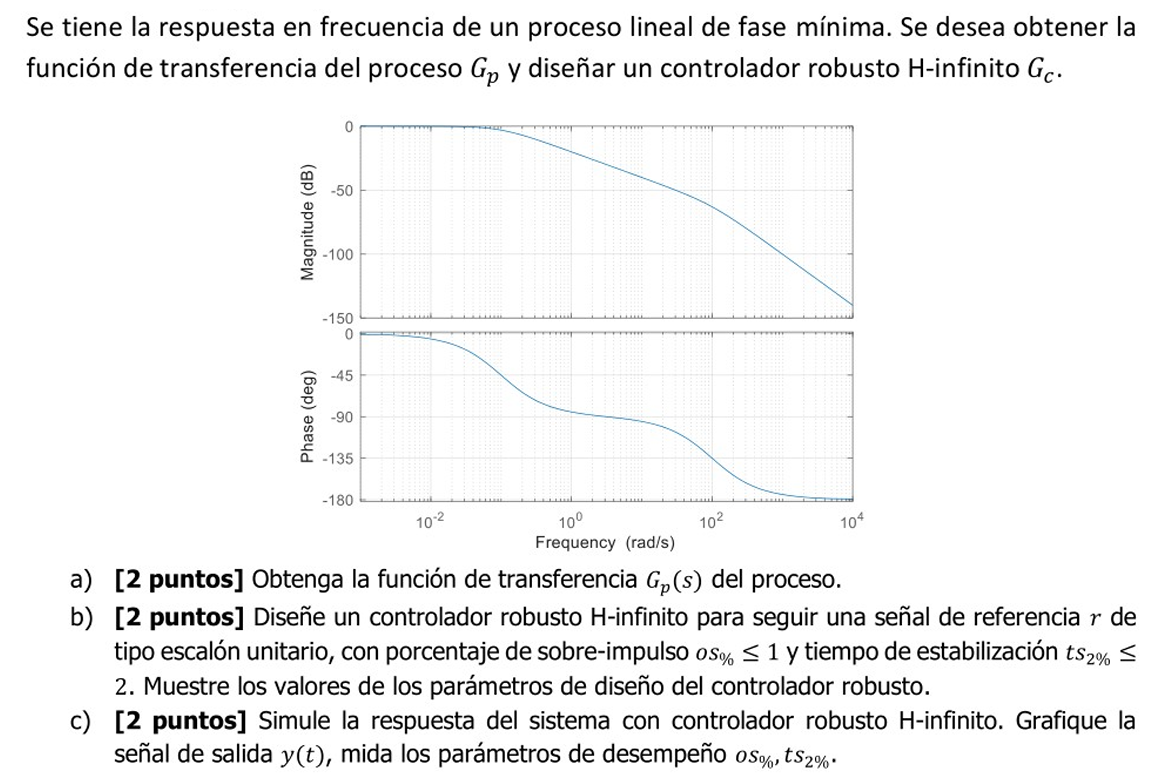

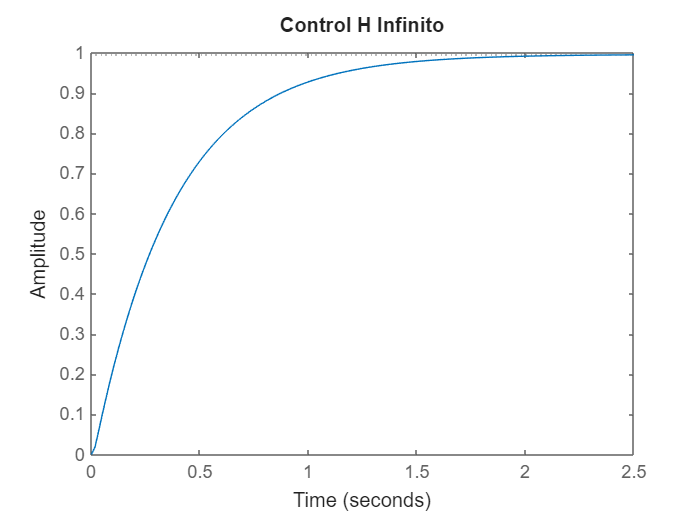

s = tf('s');
Gp = 10 / ((s + 0.1) * (s + 100));

% Configuración de Ponderadores H-Infinito
W1 = makeweight(100, [1, 1], 0.01);
W2 = 0.01;
W3 = makeweight(0.01, [1, 0.1], 100);

% Super Planta
P = augw(Gp, W1, W2, W3);

[Sc, CL, gamma] = hinfsyn(P, 1, 1);

Gt = feedback(Gp * Sc, 1);
figure; step(Gt); title('Control H Infinito');